# 20 Differences among Total, Phase-Locked, and Non-Phase-Locked Power and Intertrial Phase Consistency

This session illustrates some of the methods used for separating phase-locked from non-phase-locked power in EEG data.

## 20.1 Total Power

Total power is what you get when you take the time-frequency decomposition (through any method) of each trial and then average together the time-frequency power from all trials. This is the time-frequency approach most commonly used in the cognitive electrophysiology literature.

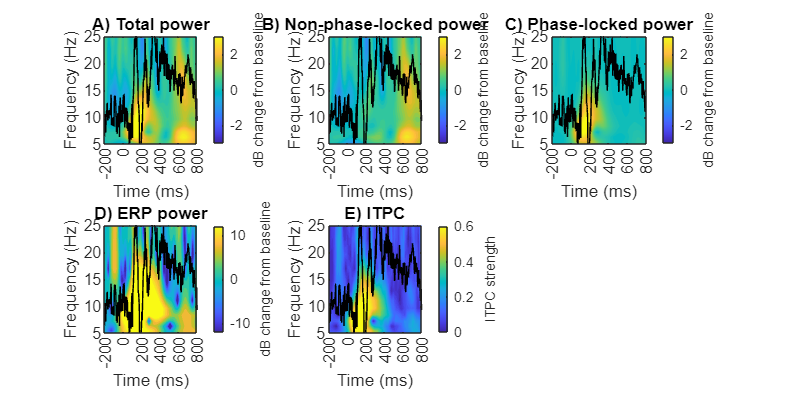

load sampleEEGdata

channel2plot = 'o1';

min_freq = 2;
max_freq = 30;
num_frex = 20;

baseline_time = [ -400 -100 ];

frequencies = logspace(log10(min_freq),log10(max_freq),num_frex);
time = -1:1/EEG.srate:1;
half_of_wavelet_size = (length(time)-1)/2;

n_wavelet     = length(time);
n_data        = EEG.pnts*EEG.trials;
n_convolution(1:2) = n_wavelet+n_data-1;
n_convolution(3)   = n_wavelet+EEG.pnts-1; 

sensoridx = find(strcmpi(channel2plot,{EEG.chanlocs.labels}));

erp = squeeze(mean(EEG.data(sensoridx,:,:),3));

induced_EEG = squeeze(EEG.data(sensoridx,:,:)) - repmat(erp',1,EEG.trials);

fft_EEG{1} = fft(reshape(EEG.data(sensoridx,:,:),1,EEG.pnts*EEG.trials),n_convolution(1)); 
fft_EEG{2} = fft(reshape(induced_EEG,1,EEG.pnts*EEG.trials),n_convolution(2)); 
fft_EEG{3} = fft(erp,n_convolution(3)); 

[~,baseidx(1)] = min(abs(EEG.times-baseline_time(1)));
[~,baseidx(2)] = min(abs(EEG.times-baseline_time(2)));

tf = zeros(4,length(frequencies),EEG.pnts);

for fi=1:length(frequencies)
    
    wavelet = exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*(4/(2*pi*frequencies(fi)))^2))/frequencies(fi);
    
    for i=1:3
        
        fft_wavelet = fft(wavelet,n_convolution(i));
        
        convolution_result_fft = ifft(fft_wavelet.*fft_EEG{i},n_convolution(i));
        convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
        
        if i<3
            convolution_result_fft = reshape(convolution_result_fft,EEG.pnts,EEG.trials);
            
            tf(i,fi,:) = mean(abs(convolution_result_fft).^2,2);
        else
            tf(i,fi,:) = abs(convolution_result_fft).^2;
        end
        
        tf(i,fi,:) = 10*log10( squeeze(tf(i,fi,:)) ./ mean(tf(i,fi,baseidx(1):baseidx(2)),3) );
        
        if i==1
            tf(4,fi,:) = abs(mean(exp(1i*angle(convolution_result_fft)),2));
        end
    end 
end 

erpt = (erp-min(erp))./max(erp-min(erp));
erpt = erpt*(frequencies(end)-frequencies(1))+frequencies(1);

figure(Position=[100,100,1200,600])

subplot(2,3,1)
contourf(EEG.times,frequencies,squeeze(tf(1,:,:)),40,'linecolor','none')
set(gca,'clim',[-3 3],'xlim',[-200 800],'xtick',-200:200:800,'ylim',[5 25],'ytick',5:5:25)
xlabel('Time (ms)')
ylabel('Frequency (Hz)')
title('A) Total power')
cb1 = colorbar;
ylabel(cb1, 'dB change from baseline')
hold on
plot(EEG.times,erpt,'k')

subplot(2,3,2)
contourf(EEG.times,frequencies,squeeze(tf(2,:,:)),40,'linecolor','none')
set(gca,'clim',[-3 3],'xlim',[-200 800],'xtick',-200:200:800,'ylim',[5 25],'ytick',5:5:25)
xlabel('Time (ms)')
ylabel('Frequency (Hz)')
title('B) Non-phase-locked power')
cb2 = colorbar;
ylabel(cb2, 'dB change from baseline')
hold on
plot(EEG.times,erpt,'k')

subplot(2,3,3)
contourf(EEG.times,frequencies,squeeze(tf(1,:,:)-tf(2,:,:)),40,'linecolor','none')
set(gca,'clim',[-3 3],'xlim',[-200 800],'xtick',-200:200:800,'ylim',[5 25],'ytick',5:5:25)
xlabel('Time (ms)')
ylabel('Frequency (Hz)')
title('C) Phase-locked power')
cb3 = colorbar;
ylabel(cb3, 'dB change from baseline')
hold on
plot(EEG.times,erpt,'k')

subplot(2,3,4)
contourf(EEG.times,frequencies,squeeze(tf(3,:,:)),40,'linecolor','none')
set(gca,'clim',[-12 12],'xlim',[-200 800],'xtick',-200:200:800,'ylim',[5 25],'ytick',5:5:25)
xlabel('Time (ms)')
ylabel('Frequency (Hz)')
title('D) ERP power')
cb4 = colorbar;
ylabel(cb4, 'dB change from baseline')
hold on
plot(EEG.times,erpt,'k')

subplot(2,3,5)
contourf(EEG.times,frequencies,squeeze(tf(4,:,:)),40,'linecolor','none')
set(gca,'clim',[0 0.6],'xlim',[-200 800],'xtick',-200:200:800,'ylim',[5 25],'ytick',5:5:25)
xlabel('Time (ms)')
ylabel('Frequency (Hz)')
title('E) ITPC')
cb5 = colorbar;
ylabel(cb5, 'ITPC strength')
hold on
plot(EEG.times,erpt,'k')

**Figure 20.1**

*Example results from different methods of computing time-frequency power and ITPC at electrode O1.*

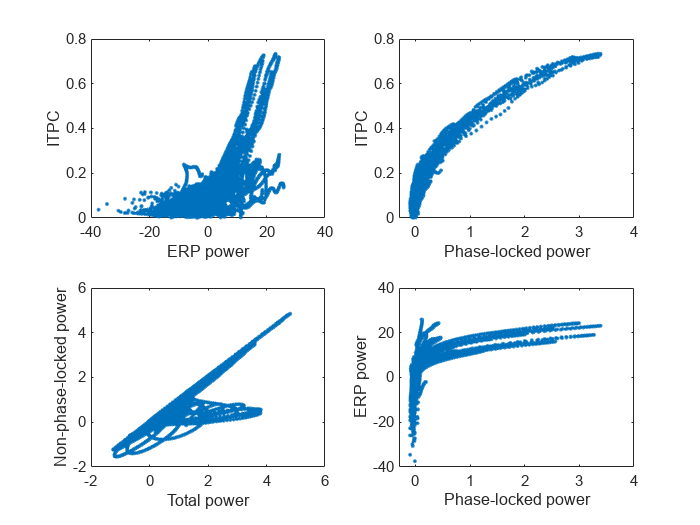

figure
subplot(221)
plot(reshape(tf(3,:,:),1,[]),reshape(tf(4,:,:),1,[]),'.')
xlabel('ERP power'), ylabel('ITPC')

subplot(222)
plot(reshape(tf(1,:,:)-tf(2,:,:),1,[]),reshape(tf(4,:,:),1,[]),'.')
xlabel('Phase-locked power'), ylabel('ITPC')
set(gca,'xlim',[-.3 4])

subplot(223)
plot(reshape(tf(1,:,:),1,[]),reshape(tf(2,:,:),1,[]),'.')
xlabel('Total power'), ylabel('Non-phase-locked power')
set(gca,'xlim',[-2 6],'ylim',[-2 6])

subplot(224)
plot(reshape(tf(1,:,:)-tf(2,:,:),1,[]),reshape(tf(3,:,:),1,[]),'.')
xlabel('Phase-locked power'), ylabel('ERP power')
set(gca,'xlim',[-.3 4])

**Figure 20.2**

*Direct comparison of results for the different methods of computing time-frequency power.*

## 20.2 Non-Phase-Locked Power

Non-phase-locked power (also sometimes called induced power) is the time-frequency representation of the data after the phase-locked components of the EEG signal are removed. There are several suggestions for how to compute Non-phase-locked power; The approach used here is to subtract the ERP from each trial and then perform a time-frequency decomposition of the single trials as you would for total power. The ERP and ITPC of non-phase-locked activity will be very close to zero. Thus, the time-frequency representation after subtraction of the ERP from each trial will show the dynamics that are task-related (if baseline normalization is applied) but do not contribute to the ERP.

## 20.3 Phase-Locked Power

If total power comprises both phase-locked and non-phase-locked activity, then it is logical that subtracting the non-phase-locked power from the total power yields the phase-locked power. Phase-locked power is also sometimes called evoked power.

Any activity that is not phase-locked to the time = 0 event will have no representation in the phase-locked power.

One way to compute phase-locked power is to subtract the non-phase-locked power from the total power. In this approach, the subtraction is done after the total and the non-phase-locked power are separately converted to a decibel scale. This is a sensible method because the baseline activity from the non-phase-locked signal is nearly identical to the baseline activity from the total signal. Furthermore, subtracting non-baseline-corrected raw power could produce negative values, which cannot be decibel-transformed. Phase-locked power defined in this way is closely related to intertrial phase consistency (ITPC), but it remains distinct from the time-frequency representation of the event-related potential (ERP).

## 20.4 ERP Time-Frequency Power

To obtain the time-frequency representation of the ERP, you compute first the ERP and then its time-frequency representation via any method.

The raw power values from an ERP time-frequency power analysis are likely to be at least an order of magnitude smaller than the raw values from the total power or the non-phase-locked power analyses. This is because the voltage values of the ERP are generally at least an order of magnitude smaller than the voltage values of single trials. On the other hand, the baseline-normalized ERP-derived power will generally have larger decibel (or percentage) change compared to total power because the ERP baseline activity is likely to contain little variability due to time-domain averaging.

It is appropriate to use the ERP baseline to normalize the ERP time-frequency power, Rather than the baseline period power from the total or non-phase-locked analysis, because: 

- There is difference in signal magnitude.

- Then the baseline would come from a different part of the signal than what is used for the ERP time-frequency power. 

Although it may initially seem awkward to have dB values in the range of 10 – 15, this is an accurate depiction of the spectral representation of the ERP signal.

## 20.5 Intertrial Phase Clustering

ITPC measures the clustering in polar space of phase angles over trials at each time-frequency point.

## 20.6 When to Use What Approach

Unless you have a reason otherwise, it is best to use total power, because: 

- This is the most commonly used approach.

- It does not involve altering data by removing part of its signal

- Its interpretation does not rely on assumptions regarding the neurophysiological events that may produce phase-locked versus non-phase-locked activity.

ERP time-frequency power does not seem to have many advantages, because: 

- There is no information available in the ERP time-frequency power that is not present in the ERP.

- The ERP has higher temporal precision. 

- The ERP may be simpler to interpret. 

- ERPs are unlikely to have a “clean” time-frequency representation with well-defined frequency components.

ERP time-frequency power may be most useful for attempts to dissociate components of the ERP by their frequency representation rather than by their latency and polarity.

Non-phase-locked power is useful in some situations: 

- To examine the relationship between the information available in time-frequency power compared to the ERP. Interpreting differences in results between phase-locked and the total power in terms of neurophysiological mechanisms relies on the assumption that the neurophysiological processes that generate the ERP are distinct from the neurophysiological processes that generate non-phase-locked activity. Some authors make this assumption.

- To help make the single-trial EEG data more likely to remain stationary for some analyses such as autoregression modeling in Granger prediction.

ITPC is best to use when there are hypotheses regarding the timing of band-specific activity over trials with respect to an experiment event such as stimulus onset or response. ITPC is advantageous over the ERP because ERPs often have relatively little frequency-band specificity. On the other hand, the temporal precision of ITPC is lower than that of ERPs.